## Load Data

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\BFLATANN\Evaporation\'
cd data\input

load('Bflat30min.mat')
load('BflatEdCov.mat')
%Radiation
% figure, stackedplot(Bflat30min(:,[11,14,10,16,15,13,1]))
% title("BFLAT radiation") 

# Subset Data - Inpat ANN BFLAT variables (InputVar) and training period (subset)

% min input - humidity, temp, time of day, wind speed, radiation
InputVar = [2,3,5,6,10,11,13,15,17] %Full radiation dataset - best results

InputVar =      2     3     5     6    10    11    13    15    17


InputVarStr = ['23561011131517']; %Paired down inputs - longer radiation continuity

fullmet = table2array(Bflat30min(:,InputVar));
subset = [1:length(bflatEdCov.AirTemp1_C)];


## Training data subset


figure
% stackedplot(bflatEdCov(subset,InputVar)); 
MetTrainingData = table2array(bflatEdCov(subset,InputVar));
LEfit = bflatEdCov.Evaporation_mm30min(subset); % Eddy covariance data
LeAnnDateTime = Bflat30min.Date_Time_MDT;

% averaging = 'hourly';
% averaging = 'daily';
averaging = 'weekly';
% averaging = 'monthly';
% averaging = 'yearly';
iterations = 20

iterations = 20

# Do not change this part of the code - can't figure out how to make work as local function

## Loop - run model 100 times to compare the output

LeAnnModelOutput(1:length(LeAnnDateTime), 1) = [NaN]; %to make a vector of appropriate length to append to 
LeAnnModelOutputCumSum(1:length(LeAnnDateTime), 1) = [NaN]; %to make a vector of appropriate length to append to 
% LeAnnModelOutputVert(1:length(LeAnnDateTime), 1) = [NaN];
% LeAnnModelOutputVertYcolOrig = (1:length(LeAnnDateTime))';
LeAnnModelOutputCumSum(1:length(LeAnnDateTime), 1) = [NaN];
LeAnnModelOutputTrainingPeriod(1:length(MetTrainingData), 1) = [NaN]; %to make a vector of appropriate length to append to 
LeAnnModelOutputTrainingPeriodCumSum(1:length(MetTrainingData), 1) = [NaN];
for ii = 1:iterations %100 %change the number of iterations

# Automatically Generated ANN script

    % Solve an Input-Output Fitting problem with a Neural Network
    % Script generated by Neural Fitting app
    % Created 10-Mar-2020 16:18:14
    %
    % This script assumes these variables are defined:
    %
    %   datamat - input data.
    %   LEfit - target data.
    
    x = MetTrainingData';
    t = LEfit';
    
    % Choose a Training Function
    % For a list of all training functions type: help nntrain
    % 'trainlm' is usually fastest.
    % 'trainbr' takes longer but may be better for challenging problems. -
    %bayesian regularization did >400 iterations, lm only does 20-70, typically r2 above 0.92. 
    % 'trainscg' uses less memory. Suitable in low memory situations. (WORST OPTION)
    trainFcn = 'trainbr';  % Levenberg-Marquardt backpropagation.
    
    % Create a Fitting Network
    hiddenLayerSize = 10;
    net = fitnet(hiddenLayerSize,trainFcn);
    
    % Setup Division of Data for Training, Validation, Testing
    net.divideParam.trainRatio = 70/100; %switch to 70
    net.divideParam.valRatio = 30/100; %switch to 25
    net.divideParam.testRatio = 0/100;
    
    % Train the Network
    [net,tr] = train(net,x,t);
    
    % Test the Network
    y = net(x);
    e = gsubtract(t,y);
    performance = perform(net,t,y)
    
    % View the Network
    %  view(net)
    
    % Plots
    % Uncomment these lines to enable various plots.
    % figure, plotperform(tr)
    % figure, plottrainstate(tr)
    % figure, ploterrhist(e)
    %% CAN UNCOMMENT DATA WITH #
    % # plotregression(t,y)
    %# print('ModelFit','-bestfit','-dpdf') 
    %figure, plotfit(net,x,t)
    %plotfit(net,y,t)
    

### Apply to full dataset

    LEann = net(fullmet');
    LEann = LEann';
    LEann = fillmissing(LEann, "linear");
    LeAnnModelOutput = [LeAnnModelOutput, LEann];
    LeAnnModelOutputCumSum = [LeAnnModelOutputCumSum, cumsum(fillmissing(LEann, "linear"))];
    % LeAnnModelOutputVert = [LeAnnModelOutputVert; LEann];
    % LeAnnModelOutputVertYcol = [LeAnnModelOutputVertYcol; LeAnnModelOutputVertYcolOrig]; %half of what it should be.
    
    LeAnnModelOutputTrainingPeriod = [LeAnnModelOutputTrainingPeriod, y'];
    LeAnnModelOutputTrainingPeriodCumSum = [LeAnnModelOutputTrainingPeriodCumSum, cumsum(fillmissing(y', "linear"))];    
end

performance = 8.5461e-06

performance = 1.1133e-05

performance = 1.0632e-05

performance = 1.1093e-05

performance = 1.0631e-05

performance = 1.1476e-05

performance = 9.7075e-06

performance = 1.0354e-05

performance = 1.0266e-05

performance = 1.0156e-05

performance = 1.1190e-05

performance = 1.0104e-05

performance = 1.0571e-05

performance = 9.6949e-06

performance = 8.7731e-06

performance = 1.0425e-05

performance = 1.0062e-05

performance = 1.6708e-05

performance = 8.7231e-06

performance = 9.6205e-06

## Compare fit quality 

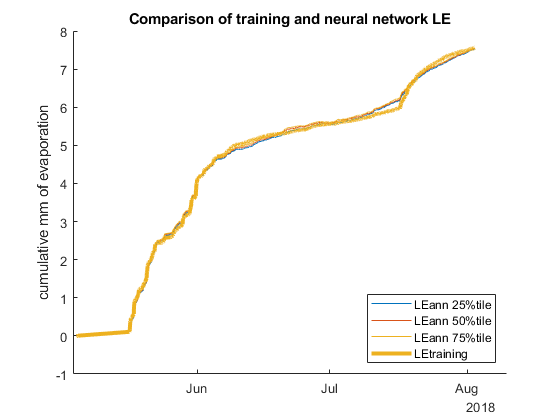

clear y performance x hiddenLayerSize trainFcn tr LEann e t ii net
LeAnnModelOutputTrainingPeriod(:,1) = [];
% LeAnnModelOutputTrainingPeriod = transpose(mean(transpose(LeAnnModelOutputTrainingPeriod)));
LeAnnModelOutputTrainingPeriodCumSum50 = prctile((LeAnnModelOutputTrainingPeriodCumSum(:,1:end)),[50],2); %maywanttoreconsider naming here
LeAnnModelOutputTrainingPeriodCumSum25 = prctile((LeAnnModelOutputTrainingPeriodCumSum(:,1:end)),[25],2); %maywanttoreconsider naming here
LeAnnModelOutputTrainingPeriodCumSum75 = prctile((LeAnnModelOutputTrainingPeriodCumSum(:,1:end)),[75],2); %maywanttoreconsider naming here

figure
hold on
plot(bflatEdCov.Date_Time_MDT, LeAnnModelOutputTrainingPeriodCumSum25, 'DisplayName', 'LEann 25%tile')
plot(bflatEdCov.Date_Time_MDT, LeAnnModelOutputTrainingPeriodCumSum50, 'DisplayName', 'LEann 50%tile')
plot(bflatEdCov.Date_Time_MDT, LeAnnModelOutputTrainingPeriodCumSum75, 'DisplayName', 'LEann 75%tile')
plot(bflatEdCov.Date_Time_MDT, cumsum(fillmissing(bflatEdCov.Evaporation_mm30min(subset), "linear")), ...
    'color', [0.9290 0.6940 0.1250],'linewidth', 3,  'DisplayName','LEtraining')
legend('location', 'southeast')
ylabel("cumulative mm of evaporation")
title('Comparison of training and neural network LE')

## Show that need to select the cumsum value... better - we bias the quartiles wide when we do this - so need to do the lower and higher data differently

Bflat30min(:,2:end) = [];
Bflat30min.LEann_mean = transpose(mean(transpose(LeAnnModelOutput(:,2:end))));
% Bflat30min.LEann_std = transpose(std(transpose(LeAnnModelOutput(:,2:end))));
Bflat30min.LEann_prctile50 = prctile((LeAnnModelOutput(:,2:end)),[50],2); %calculate percentiles
Bflat30min.LEann_prctile50cumsum = cumsum((fillmissing(Bflat30min.LEann_prctile50, "linear")));

clear LeAnnModelOutputTrainingPeriodCumSum75 LeAnnModelOutputTrainingPeriodCumSum50 LeAnnModelOutputTrainingPeriodCumSum25

## OUTPUT = LEann calculated for entire dataset

Bflat30min(:,2:end) = [];
Bflat30min.LEann_mean = transpose(mean(transpose(LeAnnModelOutput(:,2:end))));
Bflat30min.LEann_prctile50 = prctile((LeAnnModelOutput(:,2:end)),[50],2); %calculate percentiles

% Bflat30min.LEann_IQR = prctile((LeAnnModelOutput(:,2:end)),[75],2) - prctile((LeAnnModelOutput(:,2:end)),[25],2); %calculate percentiles

Bflat30min.LEann_prctile25 = prctile((LeAnnModelOutput(:,2:end)),[25],2);
Bflat30min.LEann_prctile75 = prctile((LeAnnModelOutput(:,2:end)),[75],2);

Bflat30min.LEann_CumSum_mean = transpose(mean(transpose(LeAnnModelOutputCumSum(:,2:end))));
Bflat30min.LEann_CumSum_prctile50 = prctile((LeAnnModelOutputCumSum(:,2:end)),[50],2); 


tile25column = prctile(LeAnnModelOutputCumSum(end, 1:end), 25, 2)

tile25column = 391.9869

[tile25column] = find(LeAnnModelOutputCumSum(end, :) > (tile25column - 3) & LeAnnModelOutputCumSum(end, :) < (tile25column + 3))

tile25column = 12

tile25column = tile25column(1)

tile25column = 12

Bflat30min.LEann_prctile25singlemodel = LeAnnModelOutput(:,tile25column);
Bflat30min.LEann_CumSum_prctile25 = cumsum(Bflat30min.LEann_prctile25singlemodel);

tile75column = prctile(LeAnnModelOutputCumSum(end, 1:end), 75, 2)

tile75column = 632.7318

[tile75column] = find(LeAnnModelOutputCumSum(end, :) > (tile75column - 1) & LeAnnModelOutputCumSum(end, :) < (tile75column + 1))


tile75column =

  1×0 empty double row vector



tile75column = tile75column(1)

Index exceeds the number of array elements (0).

Bflat30min.LEann_prctile75singlemodel = LeAnnModelOutput(:,tile75column);
Bflat30min.LEann_CumSum_prctile75 = cumsum(Bflat30min.LEann_prctile75singlemodel);

Bflat30min(:,1) = [];

### Effect of changing different study periods

BFLATnew = retime(Bflat30min, averaging, 'mean');

### Percentile seems effective, but large difference between 50th percentile and mean

figure
hold on 

plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_mean, 'DisplayName', 'mean')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_prctile25, 'DisplayName', '25percentile')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_prctile25singlemodel, 'DisplayName', '25percentile - single model')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_prctile50, 'DisplayName', '50percentile')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_prctile75, 'DisplayName', '75percentile')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_prctile75singlemodel, 'DisplayName', '75percentile - single model')

legend
title(['evaporation values ANN ',averaging,' mean & percentile'])
hold off

### Show cumulative sum of weekly averages?  title(['evaporation values ANN ',averaging,' averages'])

figure
hold on 
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_CumSum_prctile75, 'DisplayName', '75percentile')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_CumSum_mean, 'DisplayName', 'mean')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_CumSum_prctile50, 'DisplayName', '50percentile')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_CumSum_prctile25, 'DisplayName', '25percentile')
legend('location', 'northwest')
title("evaporation values ANN - 30 minute values, mean is much higher than 75th percentile")
hold off

figure
hold on 
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_prctile75, 'DisplayName', '75percentile')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_mean, 'DisplayName', 'mean')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_prctile50, 'DisplayName', '50percentile')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_prctile25, 'DisplayName', '25percentile')
legend
title("evaporation values ANN - 30 minute values")
hold off
% figure
% plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_IQR)
% title("IQR over time")

% clear bflatEdCov fullmet InputVar LeAnnDateTime LeAnnModelOutput LeAnnModelOutputCumSum 
% clear LeAnnModelOutputTrainingPeriodCumSum LeAnnModelOutputTrainingPeriod LEfit
% clear OUTPUT MetTrainingData subset


# Save Data - adjust the input parameters!

cd ../output/
eval(['Bflat_30minLEann_',InputVarStr, ' = Bflat30min;'])
eval (['BFLAT_', averaging, 'LEann_', InputVarStr,' = BFLATnew;'])
InputVarStr;

#### Automate this part - for now make sure the interval and input variables are correct

writetimetable(Bflat_30minLEann_23561011131517)
save('Bflat_30minLEann_23561011131517.mat','Bflat_30minLEann_23561011131517')

writetimetable(BFLAT_weeklyLEann_23561011131517)
save('BFLAT_weeklyLEann_23561011131517.mat','BFLAT_weeklyLEann_23561011131517')